clear all
clf

% filename="fusion1.xls";
% ambTemp=19+273;
dataFolder="C:\Users\griff\OneDrive\Documents\matlab\Stanford\AA272\Project\fusion attempt1\tressider\data";
ambTemp=288;
groundTruthChange=3.5052;
groundTruthABS=34+4.5212;
%Get the variance for the barometer velocities
calBaro=readtable("zeroVeloBaro.xls");

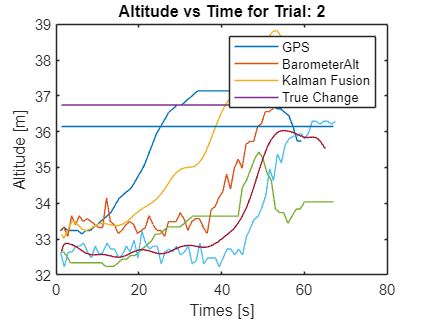

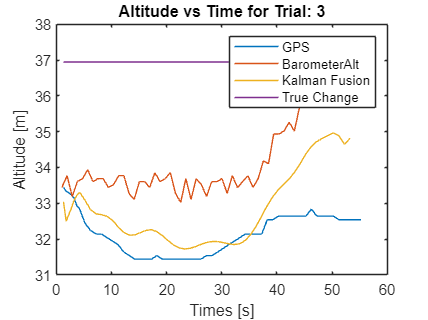

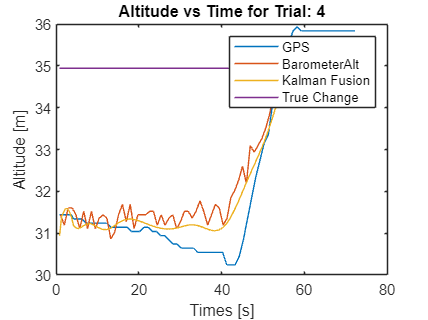

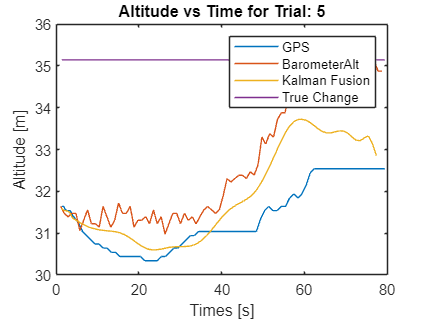

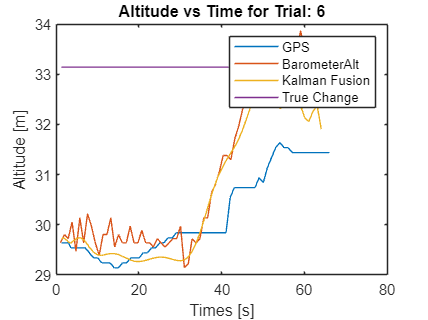

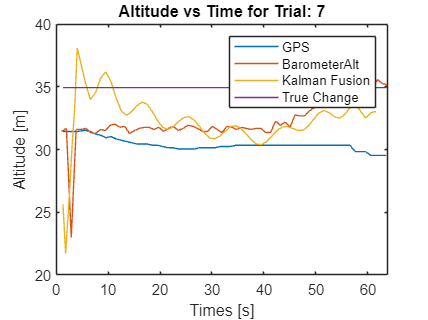

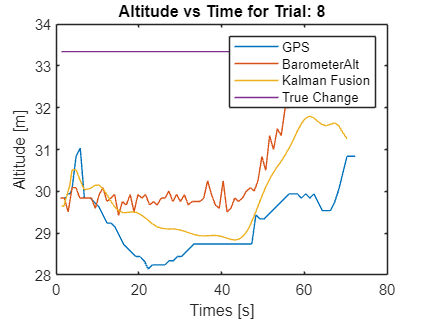

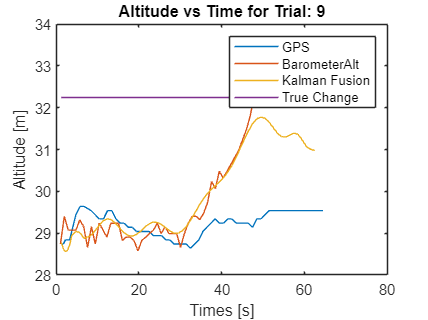

calP=calBaro.Pressure_hPa_*100;
calT=calBaro.Time_s_;
valV=getVelocities(calP,21+273,calT);
p0v=(std(valV))^2;

deltaAlt=[];
endAlt=[];

for i=1:31
    trialFolder=dataFolder+"\t"+num2str(i);
    pressureData=readtable(trialFolder+"\Pressure.csv");
    locationData=readtable(trialFolder+"\Location.csv");
    [gpsAlt,gpsTime,altVar]=gpsAnalyze(locationData);
    veloPoly=getVelocityPoly(ambTemp,pressureData,20);
    kalmanAlt=kalmanF(veloPoly,gpsAlt,gpsTime,altVar,p0v);
    
    nonNaNIndices = find(~isnan(kalmanAlt));
    if length(nonNaNIndices)>2
        endAlt=[endAlt,kalmanAlt(nonNaNIndices(end))];
        deltaAlt=[deltaAlt,kalmanAlt(nonNaNIndices(end))-kalmanAlt(nonNaNIndices(1))];
        %Plot barometer altidue based on staring GPS alt
        pressureAlt=changeInAltitude(pressureData,ambTemp);
        pressureAlt=pressureAlt+(gpsAlt(1)-pressureAlt(1));
        data=pressureData;
        pressureTimes=data.Time_s_;
        %Get approximate Velo
        approxVelo=polyval(veloPoly,pressureTimes(1:end-1));
        
        figure(i*13)
        plot(gpsTime,gpsAlt)
        hold on
        plot(pressureTimes,pressureAlt);
        plot(gpsTime(1:end-2),kalmanAlt(1:end-1))
        plot(gpsTime,zeros(length(gpsTime),1)+gpsAlt(1)+groundTruthChange)
        xlabel("Times [s]")
        ylabel("Altitude [m]")
        legend("GPS","BarometerAlt","Kalman Fusion","True Change")
        title("Altitude vs Time for Trial: "+num2str(i))
    end

end


changeError=deltaAlt-groundTruthChange;
muChangeEr=mean(changeError)

muChangeEr = -1.4686

sigChangeEr=std(changeError)

sigChangeEr = 2.1410

absEr=endAlt-groundTruthABS;
muABSEr=mean(absEr)

muABSEr = -5.8525

sigABSEr=std(absEr)

sigABSEr = 2.4178

function kalmanAlt=kalmanF(veloPolyFromBaro, gpsPos,gpsTimes,gpsAltVar,pVelo)
    estimatedVelos=polyval(veloPolyFromBaro,gpsTimes);
    deltaTs=diff(gpsTimes);
    
    ptemp=gpsAltVar(1);
    xTemp=gpsPos(1);
    vTemp=estimatedVelos(1);
    tempDt=deltaTs(1);
    rTemp=gpsAltVar(1);
    
    kalmanAlt=[];
    for i=2:length(gpsPos)
        %Update
        rTemp=gpsAltVar(i);
        Ktemp=ptemp/(ptemp+rTemp);
        xTT=xTemp+Ktemp*(gpsPos(i)-xTemp);
        pTT=(1-Ktemp)*ptemp;
        %Predict
        xTemp=xTT+deltaTs(i-1)*estimatedVelos(i-1);
        ptemp=pTT+(deltaTs(i-1))^2*pVelo;
        kalmanAlt=[kalmanAlt;xTemp];
    end
end

function veloPoly=getVelocityPoly(tempInfo,data,numPoly)
    if ~isa(tempInfo,"double")
        weatherData=readtable(tempInfo);
        [groundTemp,groundPressure,lbArr]=getWeatherForMeasurment(filename,pressureTimes,weatherData);
    else
        groundTemp=tempInfo;
    end
    % data=readtable(filename,Sheet="Pressure");
    pressures=data.Pressure_hPa_*100;%pressures from phone barometer in Pa
    pressureTimes=data.Time_s_;%Times since start of pressure measurments
    lb=-.0065*ones(length(pressures),1);%Standard temperature lapse rate
    R=8.31432;%universal gas constant
    g=9.80665;%Gravity
    M=0.0289644;%Molar mass of air
    velos=getVelocities(pressures,groundTemp,pressureTimes);
    veloPoly=polyfit(pressureTimes(1:end-1),velos,numPoly);
end

function veloArray=getVelocities(pressure,temperature,times)
    lb=-.0065*ones(length(pressure),1);%Standard temperature lapse rate
    R=8.31432;%universal gas constant
    g=9.80665;%Gravity
    M=0.0289644;%Molar mass of air
    veloArray=zeros(length(pressure)-1,1);
    if isscalar(temperature)
        temperature=ones(length(pressure),1)*temperature;
    end
    if isscalar(lb)
        lb=ones(length(pressure),1)*lb;
    end
    for i=1:(length(pressure)-1)
    veloArray(i)=calculatVelo(pressure(i),pressure(i+1),temperature(i),lb(i),R,g,M,times(i+1),times(i));

    end

end

function velo=calculatVelo(p0,p1,temp,lb,R,g,M,t2,t1)
    velo=(temp/lb*((p1/p0)^(-R*lb/(g*M))-1))/(t2-t1);
end

function [gpsAlt,gpsTime,altVar]=gpsAnalyze(data)
    % data=readtable(filename,Sheet="Location");
    gpsAlt=data.Height_m_;
    gpsTime=data.Time_s_;
    altVar=(data.VerticalAccuracy_m_).^2;

end

function deltaAltitudeArray=changeInAltitude(data,temperature)
    % data=readtable(filename,Sheet="Pressure");
    pressure=data.Pressure_hPa_*100;
    lb=-.0065*ones(length(pressure),1);%Standard temperature lapse rate
    R=8.31432;%universal gas constant
    g=9.80665;%Gravity
    M=0.0289644;%Molar mass of air
    if isscalar(temperature)
        temperature=ones(length(pressure),1)*temperature;
    end
    if isscalar(lb)
        lb=ones(length(pressure),1)*lb;
    end
    deltaAltitudeArray=zeros(length(pressure),1);
    p0=pressure(1);
    for i=1:length(temperature)
        deltaAltitudeArray(i)=calculateAlt(p0,pressure(i),0,temperature(i),lb(i),R,g,M);
    
    end

end

function altitude=calculateAlt(p0,p1,h0,temp,lb,R,g,M)
    altitude=h0+temp/lb*((p1/p0)^(-R*lb/(g*M))-1);
end


